strike = 1.1

strike = 1.1000

valueDate = datetime(2008,02,15)

valueDate = datetime
   15-Feb-2008


timeToMaturity = 1/3

timeToMaturity = 0.3333

volatility = 0.212

volatility = 0.2120

discountRate = 0.025 

discountRate = 0.0250

dividendYield = 0.02

dividendYield = 0.0200

nominal = 1e6

nominal = 1000000

underlyingPrice = 1

underlyingPrice = 1

blkprice: 

forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
analyticOptionOnForwardPrice = blkprice(forwardPrice,strike,discountRate,timeToMaturity,volatility)

analyticOptionOnForwardPrice = 0.0163

CRR Tree Approach Notice when number of timesteps is 10, we get a very accurate model because we are lucky, precision must be sawtooth function of some sorts. Run this with 11 timesteps, it will be worse than with 10, but as N increases the errors dampen. 

numberOfTimesteps = 2e3

numberOfTimesteps = 2000

timestepSize = timeToMaturity / numberOfTimesteps;
yieldAdjustedDiscountRate = discountRate - dividendYield

yieldAdjustedDiscountRate = 0.0050

forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
dx = volatility * sqrt(timestepSize);
u = exp(dx);
d = 1/u;

yieldAdjustedGrowthFactorAtTimeStep = 1

yieldAdjustedGrowthFactorAtTimeStep = 1

riskNeutralProbabilityUpCRR = (yieldAdjustedGrowthFactorAtTimeStep - d) / (u - d);

numberOfUpMovements = (0:numberOfTimesteps)';
numberOfDownMovements = numberOfTimesteps - numberOfUpMovements;
netMovements = numberOfUpMovements - numberOfDownMovements;

forwardPriceAtMaturity = exp(log(forwardPrice) + netMovements * dx);

binomialRiskNeutralProbabilities = binopdf(numberOfUpMovements, numberOfTimesteps, riskNeutralProbabilityUpCRR);
optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

expectedPayoffs = binomialRiskNeutralProbabilities .* optionPayoffs;

crrOptionOnforwardPrice = exp(-discountRate * timeToMaturity) * sum(expectedPayoffs)

crrOptionOnforwardPrice = 0.0163

Monte Carlo Approach I think 1e8 

numberOfPaths = 1e6; 
forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
epsilon = randn(numberOfPaths, 1);
unitForwardPriceAtMaturityPaths = (volatility * sqrt(timeToMaturity) * epsilon) - ...
                      (0.5 * volatility^2 * timeToMaturity);

forwardPriceAtMaturity = forwardPrice * exp(unitForwardPriceAtMaturityPaths);

optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

expectedFuturePayoff = mean(optionPayoffs);

monteCarloOptionOnForwardPrice = exp(-discountRate * timeToMaturity) * expectedFuturePayoff

monteCarloOptionOnForwardPrice = 0.0163

Log log ( notice after M > 1e6, we have a problem due to numerical stability I think (because of the probabilities getting really small after so many steps) 

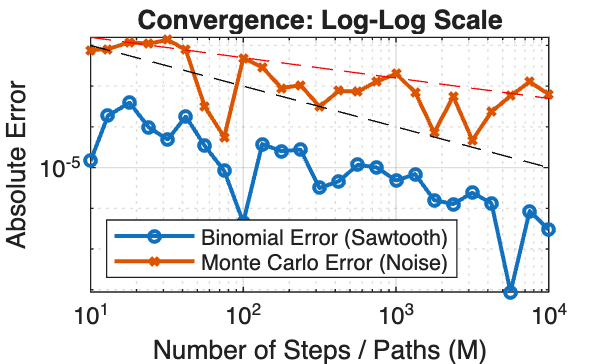

% --- Parameters ---
strike = 1.1;
timeToMaturity = 1/3;
volatility = 0.212;
discountRate = 0.025; 
dividendYield = 0.02;
underlyingPrice = 1;

% Analytical Black-76 Price (The "True" Target)
F = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
d1 = (log(F/strike) + (0.5 * volatility^2) * timeToMaturity) / (volatility * sqrt(timeToMaturity));
d2 = d1 - volatility * sqrt(timeToMaturity);
exactPrice = exp(-discountRate * timeToMaturity) * (F * normcdf(d1) - strike * normcdf(d2));

% Ranges for M (using powers of 10 to see the log-log trend)
M_range = round(logspace(1, 4, 25)); % 10 to 10,000
binomErrors = zeros(size(M_range));
mcErrors = zeros(size(M_range));

for i = 1:length(M_range)
    M = M_range(i);
    
    % --- Binomial Calculation ---
    dt = timeToMaturity / M;
    dx = volatility * sqrt(dt);
    u = exp(dx); d = 1/u;
    p = (1 - d) / (u - d);
    upMoves = (0:M)';
    ST = F * exp((2*upMoves - M) * dx);
    binomPrice = exp(-discountRate * timeToMaturity) * sum(binopdf(upMoves, M, p) .* max(ST - strike, 0));
    binomErrors(i) = abs(binomPrice - exactPrice);
    
    % --- Monte Carlo Calculation ---
    % We use M paths to show how much worse MC is for the same 'M'
    shocks = randn(M, 1);
    fT = F * exp(-0.5 * volatility^2 * timeToMaturity + volatility * sqrt(timeToMaturity) * shocks);
    mcPrice = exp(-discountRate * timeToMaturity) * mean(max(fT - strike, 0));
    mcErrors(i) = abs(mcPrice - exactPrice);
end

% --- Log-Log Plotting ---
figure('Color', 'w');
loglog(M_range, binomErrors, '-o', 'LineWidth', 1.5, 'MarkerSize', 4);
hold on;
loglog(M_range, mcErrors, '-x', 'LineWidth', 1.5, 'MarkerSize', 4);

% Add reference slopes
% Binomial ~ 1/M (Slope
 %(-1) | MC ~ 1/sqrt(M) (Slope -0.5)
loglog(M_range, 0.1./M_range, '--k', 'HandleVisibility', 'off'); 
loglog(M_range, 0.05./sqrt(M_range), '--r', 'HandleVisibility', 'off');

grid on;
xlabel('Number of Steps / Paths (M)');
ylabel('Absolute Error');
title('Convergence: Log-Log Scale');
legend('Binomial Error (Sawtooth)', 'Monte Carlo Error (Noise)', 'Location', 'southwest');

Euro Barrier Option Up and Out - Analytic

barrierLevel = 1.4

barrierLevel = 1.4000

spreadPrice = blkprice(forwardPrice,strike,discountRate,timeToMaturity,volatility) - blkprice(forwardPrice,barrierLevel,discountRate,timeToMaturity,volatility)

spreadPrice = 0.0161

d2 = (log(forwardPrice/barrierLevel) - sigma*sigma*(timeToMaturity))/(sigma*sqrt(timeToMaturity))

d2 = -2.8455

cashOrNothingPrice = exp(-discountRate*timeToMaturity)* normcdf(d2)

cashOrNothingPrice = 0.0022

europeanBarrierAnalytic = spreadPrice - (barrierLevel - strike)*cashOrNothingPrice

europeanBarrierAnalytic = 0.0155

Euro Barrier Option Up and Out - CRR

numberOfTimesteps = 2e3

numberOfTimesteps = 2000

timestepSize = timeToMaturity / numberOfTimesteps;
forwardPrice = underlyingPrice * exp((discountRate - dividendYield) * timeToMaturity);
dx = volatility * sqrt(timestepSize);
u = exp(dx);
d = 1/u;

yieldAdjustedGrowthFactorAtTimeStep = 1

yieldAdjustedGrowthFactorAtTimeStep = 1

riskNeutralProbabilityUpCRR = (yieldAdjustedGrowthFactorAtTimeStep - d) / (u - d);

numberOfUpMovements = (0:numberOfTimesteps)';
numberOfDownMovements = numberOfTimesteps - numberOfUpMovements;
netMovements = numberOfUpMovements - numberOfDownMovements;

forwardPriceAtMaturity = exp(log(forwardPrice) + netMovements * dx);

binomialRiskNeutralProbabilities = binopdf(numberOfUpMovements, numberOfTimesteps, riskNeutralProbabilityUpCRR);
optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

expectedPayoffs = binomialRiskNeutralProbabilities .* optionPayoffs;

crrOptionOnforwardPrice = exp(-discountRate * timeToMaturity) * sum(expectedPayoffs)

crrOptionOnforwardPrice = 0.0163

Monte Carlo European Style Barrier

numberOfPaths = 1e7; 
epsilon = randn(numberOfPaths, 1);

% Jump straight to maturity
FT = forwardPrice * exp(-0.5*volatility^2*timeToMaturity + volatility*sqrt(timeToMaturity)*epsilon);

% Payoff: max(FT-K, 0) ONLY IF FT < Barrier
optionPayoffs = (FT - strike);
optionPayoffs(FT < strike | FT >= barrierLevel) = 0; % Kill outside the range

expectedFuturePayoff = mean(optionPayoffs);
monteCarloPrice = exp(-discountRate * timeToMaturity) * expectedFuturePayoff;

Monte Carlo American Barrier

numberOfPaths = 1e5; % Reduced slightly for memory (Paths x Steps)
numberOfSteps = 2000; 
dt = timeToMaturity / numberOfSteps;

% 1. Generate incremental shocks for every step
% Each row is a time step, each column is a path
epsilon = randn(numberOfSteps, numberOfPaths);

% 2. Calculate the drift and diffusion per step
% For a Forward/Future-based simulation, the drift is -0.5 * sigma^2 * dt
drift = -0.5 * volatility^2 * dt;
diffusion = volatility * sqrt(dt) * epsilon;

% 3. Cumulate the log-returns to build the paths
% We start from the current Forward Price
logForwardPaths = log(forwardPrice) + cumsum(drift + diffusion, 1);
forwardPaths = exp(logForwardPaths);

% 4. Identify Knock-outs
% If the maximum value in a column (path) >= barrier, it's out
hitBarrier = any(forwardPaths >= barrierLevel, 1);

% 5. Calculate Payoffs
forwardPriceAtMaturity = forwardPaths(end, :);
optionPayoffs = max(forwardPriceAtMaturity - strike, 0);

% Set payoffs to zero for paths that hit the barrier
optionPayoffs(hitBarrier) = 0;

% 6. Average and Discount
expectedFuturePayoff = mean(optionPayoffs);
monteCarloBarrierPrice = exp(-discountRate * timeToMaturity) * expectedFuturePayoff;

Bermudan CRR

exerciseRelativeTimes = [0.5, 1.5, 2.5, 3.5] / 4; 
exerciseSteps = round(exerciseRelativeTimes * numberOfTimesteps);

%% --- Backward Induction Loop ---
% 1. Initialize at Maturity (Step 2000)
% We calculate the terminal forward prices just like your blueprint
numberOfUpMovements = (0:numberOfTimesteps)';
S_T = exp(log(forwardPrice) + (2*numberOfUpMovements - numberOfTimesteps) * dx);
V = max(S_T - strike, 0); % Option value at T (Use max(strike - S_T, 0) for a Put)

% 2. Loop backwards from T-1 to 0
for i = numberOfTimesteps:-1:1
    % Calculate Continuation Value (Expectation)
    V = exp(-discountRate * timestepSize) * ...
        (riskNeutralProbabilityUpCRR * V(2:end) + (1 - riskNeutralProbabilityUpCRR) * V(1:end-1));
    
    % Check if this step 'i-1' is an End-of-Month exercise date
    if any((i-1) == exerciseSteps)
        % Reconstruct Forward Prices at this specific time slice
        % There are 'i' nodes at timestep 'i-1'
        currentUps = (0:i-1)';
        S_current = exp(log(forwardPrice * exp(-(numberOfTimesteps-(i-1))*timestepSize*0)) + ... % Adjustment for drift
                    (2*currentUps - (i-1)) * dx); 
        
        % In a CRR tree for forwards, we need to ensure the local forward 
        % price is consistent with the global forwardPrice:
        S_node = forwardPrice * (u.^(currentUps)) .* (d.^((i-1)-currentUps)) * exp(-(numberOfTimesteps-(i-1))*0);

        % Intrinsic Value (Exercise Now)
        intrinsic = max(S_node - strike, 0);
        
        % The Bermudan Decision: Max(Wait, Exercise)
        V = max(V, intrinsic);
    end
end

bermudanOptionPrice = V

bermudanOptionPrice = 0.0163